k_e = 0.3824

k_e = 0.3824

k_m = 0.3824

k_m = 0.3824

J = 0.0019

J = 0.0019

R = 4.6296

R = 4.6296

L = 1.1194

L = 1.1194


t = linspace(0, 3);
k = 1 / k_e

k = 2.6151

xi = (R / 2) * sqrt(J / (L * k_m * k_e))

xi = 0.2494

Ts = sqrt((J * L) / (k_e * k_m))

Ts = 0.1206


num_s = k

num_s = 2.6151

den_s = [Ts^2, 2 * Ts * xi, 1, 0]

den_s =     0.0145    0.0602    1.0000         0


sys_s = tf(num_s, den_s);

num_i = [k];
den_i = [Ts^2, 2 * Ts * xi, 1];
sys_i = tf(num_i, den_i);

%{
y_ir = (k / (Ts * sqrt(1 - xi^2))) * exp(-(xi / Ts) * t) .* sin ((sqrt(1 - xi^2) * t) / Ts)


num_i = [k];
den_i = [Ts^2, 2 * Ts * xi, 1];
sys_i = tf(num_i, den_i);

plot(t, y_ir, 'c', LineWidth=1.5)
hold on
impulse(sys_i, 'k--')
legend('y_{i.r.} - аналитика', 'y_{i.r.} - симуляция')
title('Весовая функция для ДПТ 2.0')
grid()
ylabel("f(t)")
xlabel('t')
hold off


y_sr = k - k * exp(-(xi * t) / Ts) .* cos((sqrt(1 - xi^2) * t) / Ts) - (k * xi) / sqrt(1 - xi^2) * exp(-(xi * t) / Ts) .* sin((sqrt(1 - xi^2) * t) / Ts)



plot(t, y_sr, 'c', LineWidth=1.5)
hold on
impulse(sys_s, 'k--')
legend('y_{s.r.} - аналитика', 'y_{s.r.} - симуляция')
title('Переходная функция для ДПТ 2.0')
grid()
ylabel("f(t)")
xlabel('t')
hold off
%}



w = linspace(0, 50)

w =          0    0.5051    1.0101    1.5152    2.0202    2.5253    3.0303    3.5354    4.0404    4.5455    5.0505    5.5556    6.0606    6.5657    7.0707    7.5758    8.0808    8.5859    9.0909    9.5960   10.1010   10.6061   11.1111   11.6162   12.1212   12.6263   13.1313   13.6364   14.1414   14.6465   15.1515   15.6566   16.1616   16.6667   17.1717   17.6768   18.1818   18.6869   19.1919   19.6970   20.2020   20.7071   21.2121   21.7172   22.2222   22.7273   23.2323   23.7374   24.2424   24.7475



P = k * (1 - Ts^2 * w .* w) / ((1 - Ts^2 * w .* w).^2 + 4 * Ts^2 * xi * w .* w)

P = -0.0909

Q = -2 * k * Ts * xi * w / ((1 - Ts^2 * w .* w).^2 + 4 * Ts^2 * xi * w .* w)

Q = -0.0091

%{
ach = k ./ sqrt(((1 - Ts^2 * w .* w).^2 + 4 * Ts^2 * xi * w .* w))
figure('Position', [1000 0 800 450])

plot(w, ach, LineWidth=1.5)

grid("on")
ylabel('A')
xlabel('\omega, rad/s')
legend('АЧХ')
title('Амплитудно-частотная характеристика')
%}

ph1 = atan2(-2 * k * Ts * xi * w ./ ((1 - Ts^2 * w .* w).^2 + 4 * Ts^2 * xi * w .* w), k * (1 - Ts^2 * w .* w) ./ ((1 - Ts^2 * w .* w).^2 + 4 * Ts^2 * xi * w .* w)) * 180 / pi

ph1 =          0   -1.7466   -3.5293   -5.3865   -7.3613   -9.5050  -11.8807  -14.5696  -17.6782  -21.3501  -25.7804  -31.2330  -38.0515  -46.6361  -57.3204  -70.0680  -84.0988  -97.9567 -110.2770 -120.4478 -128.5392 -134.9152 -139.9681 -144.0236 -147.3278 -150.0607 -152.3536 -154.3023 -155.9780 -157.4340 -158.7110 -159.8403 -160.8465 -161.7490 -162.5634 -163.3023 -163.9759 -164.5929 -165.1603 -165.6840 -166.1690 -166.6197 -167.0397 -167.4321 -167.7997 -168.1448 -168.4696 -168.7757 -169.0650 -169.3387


%ph2 = atan( (-2 * k * Ts * xi * w ./ ((1 - Ts^2 * w .* w).^2 + 4 * Ts^2 * xi * w .* w))./ (k * (1 - Ts^2 * w .* w) ./ ((1 - Ts^2 * w .* w).^2 + 4 * Ts^2 * xi * w .* w))) * 180 / pi

%{
figure('Position', [1000 0 800 450])

plot(w, ph1, 'LineWidth', 1.5,'DisplayName', 'ФЧХ')
title('Фазово-частотная характеристика')
legend()
ylabel('φ, degrees')
xlabel('ω, rad / s')
grid("on")
%}

figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ'

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.Title.FontSize = 15

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.XLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.YLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

   
h = bodeplot(sys_i, 'c', ops)


h =

	resppack.bodeplot



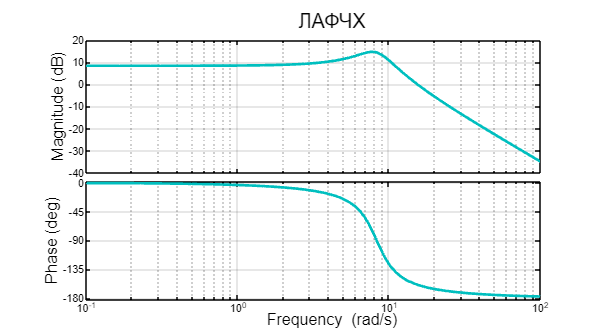

grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


%ax = findall(gcf,'type','axes');
%legend(ax(2),'ЛАЧХ');
%legend(ax(3),'ЛФЧХ');
%legend('ЛАЧХ','ЛФЧХ');



